#     Landmark localization 2d

Simulation of a robot moving in a 2d plane. Measurements are taken by beacons ( which transmit the range back to the robot ) and other sensors.

Date Started : 13 Dec. 2023 , 4: 30 PM

Author : Giorgio Ridolfi

## Sources

1) [https://stackoverflow.com/questions/39818915/matlab-how-to-get-the-specs-of-the-host-machine](https://stackoverflow.com/questions/39818915/matlab-how-to-get-the-specs-of-the-host-machine)

2) [https://undocumentedmatlab.com/](https://undocumentedmatlab.com/)

3) Ristic, Branko, Sanjeev Arulampalam, and Neil Gordon. Beyond the Kalman filter: Particle filters for tracking applications. Artech house, 2003.

4) [https://it.mathworks.com/help/matlab/ref/plot3.html#f30-448776_sep_mw_3a76f056-2882-44d7-8e73-c695c0c54ca8](https://it.mathworks.com/help/matlab/ref/plot3.html#f30-448776_sep_mw_3a76f056-2882-44d7-8e73-c695c0c54ca8)

## System Info

close all
clc
display("OS : " + computer("arch") + ", " + feature('GetOS') )

    "OS : glnxa64, Linux 6.5.6-76060506-generic #202310061235~1697396945~22.04~9283e32 SMP PREEMPT_DYNAMIC Sun O x86_64"



display("Processor : " + feature('GetCPU') + ", " + feature('numCores') )

    "Processor : 11th Gen Intel(R) Core(TM) i7-11370H @ 3.30GHz, 4"



GPU = gpuDevice

GPU =   CUDADevice with properties:

                      Name: 'NVIDIA GeForce RTX 3050 Laptop GPU'
                     Index: 1
         ComputeCapability: '8.6'
            SupportsDouble: 1
     GraphicsDriverVersion: '545.29.02'
               DriverModel: 'N/A'
            ToolkitVersion: 11.8000
        MaxThreadsPerBlock: 1024
          MaxShmemPerBlock: 49152 (49.15 KB)
        MaxThreadBlockSize: [1024 1024 64]
               MaxGridSize: [2.1475e+09 65535 65535]
                 SIMDWidth: 32
               TotalMemory: 4091478016 (4.09 GB)
           AvailableMemory: 4006608896 (4.01 GB)
               CachePolicy: 'balanced'
       MultiprocessorCount: 16
              ClockRateKHz: 1057000
               ComputeMode: 'Default'
      GPUOverlapsTransfers: 1
    KernelExecutionTimeout: 1
          CanMapHostMemory: 1
           DeviceSupported: 1
           DeviceAvailable: 1
            Devic

clear all


## Generation of poses

We first generate a set of desired poses. From these, we create noisy system inputs to feed our robot by adding gaussian noise to the true inputs. Then we calculate the robot's actual poses

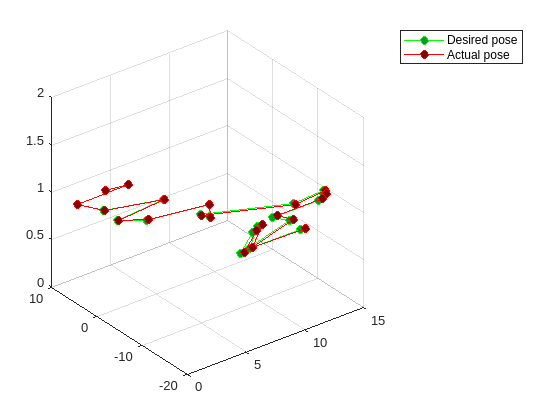

N =20;
pose = zeros(3,N+1); % x_meters y_meters theta_radians
pose_0 = [ randi(10) ; randi(10) ; randi([0 360])  ];
pose(:,1) = pose_0;
u = zeros(3,N); 
real_pose = zeros(3,N+1); 
real_pose( : , 1 ) = pose_0;

% Random walk params
stdx = 3;
stdy = 3;
th_max = 1; % Degrees

stdtr = 0.1;
stdrot = 0.01745329251*0.5;


for i = 1 : N

 x_incr = stdx*randn() ;
 y_incr = stdy*randn();
 th_incr = 0.01745329251*randi( [-th_max th_max] ) ;
 
 pose(:,i+1) = pose(:,i) +  [ x_incr ; y_incr ; th_incr ] ; 

 transl = sqrt( x_incr*x_incr + y_incr*y_incr ) ;
 rot1 = atan2(y_incr,x_incr) ;
 rot2 = pose(3,i+1) - pose(3,i) - rot1 ;
 
 u(:,i) = [ transl + stdtr*randn()  ; rot1 + stdrot*randn() ; rot2 + stdrot*randn() ];


 real_pose(3,i+1) = real_pose(3,i) + u(2,i);
 real_pose(1,i+1) = real_pose(1,i) + u(1,i)*cos( u(2,i) );
 real_pose(2,i+1) = real_pose(2,i) + u(1,i)*sin( u(2,i) );
 real_pose(3,i+1) = real_pose(3,i) + u(3,i) ;

end


figure
plot3( pose(1,:), pose(2,:) , ones(1,N+1) , '-o','Color','green','MarkerSize',6,'MarkerFaceColor','#049E22')
hold on
grid on
plot3(real_pose(1,:) , real_pose(2,:) , ones(1,N+1) , '-o','Color','r','MarkerSize',6, 'MarkerFaceColor','#7D0503' )
legend("Desired pose" , "Actual pose")

## Creation of arena 

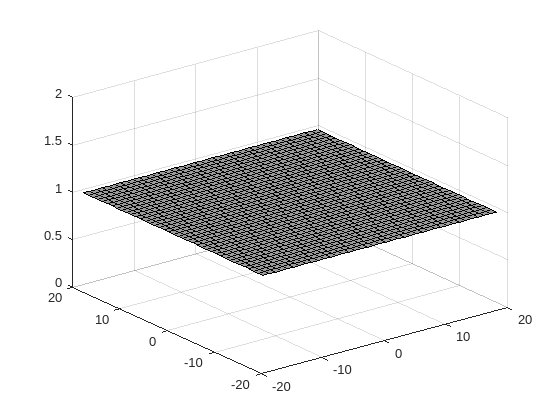

A = [ abs(pose(1,:)) ; abs(pose(2,:)) ; abs(real_pose(1,:)) ; abs(real_pose(2,:)) ];
dim_bound = ceil(max( A , [] , 'all' ));
x_bounds = [-dim_bound:1:dim_bound];
y_bounds = [-dim_bound:1:dim_bound];
index = length(x_bounds);
z_surf = ones(index);

figure
surf(x_bounds,y_bounds,z_surf,"FaceColor","#9B9B9B")
hold on

## Creation of landmarks

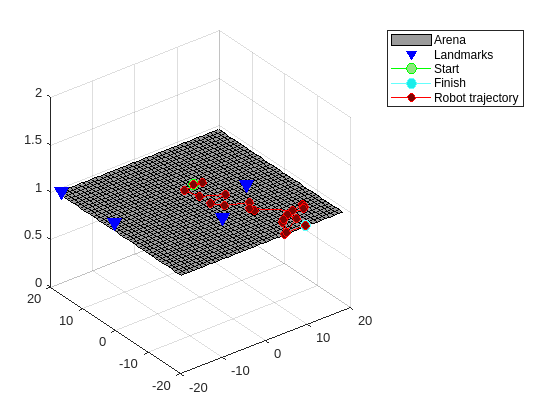

num_landmarks = 4;
coord_landmarks = zeros(3, num_landmarks);
for i = 1 : num_landmarks
    x_lm = randi(index);
    y_lm = randi(index);
    coord_landmarks(:,i) = [x_bounds(x_lm) ; y_bounds(y_lm) ; z_surf(y_lm , x_lm)];
end
scatter3(coord_landmarks(1,:) , coord_landmarks(2,:) , coord_landmarks(3,:) , 80 , 'b' , 'filled' , 'v' , 'MarkerEdgeColor','flat' , 'MarkerFaceColor','flat') 
plot3(real_pose(1,1) , real_pose(2,1) , 1 , '-o','Color','green','MarkerSize',8, 'MarkerFaceColor','#8EE67F' )
plot3(real_pose(1,N+1) , real_pose(2,N+1) , 1 , '-o','Color','#64FFFD','MarkerSize',8, 'MarkerFaceColor','#1BEDEA' )
plot3(real_pose(1,:) , real_pose(2,:) , ones(1,N+1) , '-o','Color','r','MarkerSize',6, 'MarkerFaceColor','#7D0503' )
legend("Arena" , "Landmarks" ,"Start" ,"Finish", "Robot trajectory"  )



clear x_incr y_incr th_incr transl rot1 rot2 z_surf A x_lm y_lm  
coord_landmarks

coord_landmarks =    -17    11   -18     0
     4     0    19    -7
     1     1     1     1


## SLAM

% % Assume that the location of the landmarks is not known a priori. This is
% % coded in the form of a huge initial covariance

## APPENDIX : Functions

% function [ranges_out , bearings_out ] = hRadar(x_in , lm_coords)
% % Usage : pass an xyz position and obtain a number of measurements
% % corresponding to the 2*length(lm_coords) , representing range and bearing
% % of every landmark wrt to current robot position
% sizes_lm = size(lm_coords);
% num_lm = sizes_lm(1);
% 
% 
% 
% end
